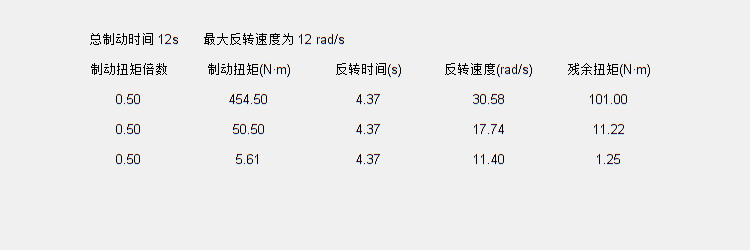

索引超过数组元素的数量。索引不能超过 2。

% 假设的数据
data = {
    '制动扭矩倍数', '制动扭矩(N·m)', '反转时间(s)', '反转速度(rad/s)', '残余扭矩(N·m)',
    '0.50', '454.50', '4.37', '30.58', '101.00';
    '0.50', '50.50', '4.37', '17.74', '11.22';
    '0.50', '5.61', '4.37', '11.40', '1.25'
};

data2={"总制动时间 12s","最大反转速度为 12 rad/s"};

% 参数名称
titles = {'制动扭矩倍数', '制动扭矩(N·m)', '反转时间(s)', '反转速度(rad/s)', '残余扭矩(N·m)'};

% 创建图形窗口
fig = figure('Position', [400, 300, 750, 250], 'Name', '参数显示');
% Notice：数值参数左到右分别为窗口中心的在屏幕的x，y坐标，窗口的长宽






%创建文本控件显示数据
for i = 1:size(data, 1)
    for j = 1:size(data, 2)
        txt_data = uicontrol('Style', 'text', ...
            'Position', [70 + (j-1)*120, 170 + (i-1)*(-30), 120, 20], ... % 第2个数值的步进值最好与第三个相等
            'FontSize', 10, ...
            'HorizontalAlignment', 'center', ...
            'String', data{i, j});
    end
end

for i = 1:3
     txt_data = uicontrol('Style', 'text', ...
            'Position', [55 + (i-1)*140, 200, 160, 20], ... % 第2个数值的步进值最好与第三个相等
            'FontSize', 10, ...
            'HorizontalAlignment', 'center', ...
            'String', data2{i});
end



% Notice：数值参数左到右对应着元素在窗口的x，y坐标，以及元素的长宽大小
% Notice：此角度上常数项具有新的几何意义
% Notice：数值之间有大小包容关系原则、不能瞎填写
% Notice:unicontrol控件连续展示参数文本时可以手动销毁上一次展示内容也可以
%        同窗口继续展示文本

% Notice：(ax,by)光标，当(a>0&b>0)时表示从左到右，从下到上移动
% 当(a>0&b<0)时表示从左到右，从上到下移动，该光标可能是读取光标也可能是放置光标
% 研究课题：figure组件内元素的绝对摆放和相对摆放